opts = bode_options_helper(1,1e4);
load PlantTF_hard.mat
load PlantTF_easy.mat;
load controller_sample.mat
C_sample = shapeit_data.C_tf;
clear shapeit_data;

x0 = generate_feasible_points_LHS(controller_flag, criteria_flag, 100,1, P, 20);

s = tf('s');
m = 0.5;
k = 1e6;
c = 5;
mass_plant = 1/(m*s^2);
mass_spring_plant = 1/(k + c*s + m*s^2);
bode(mass_plant, mass_spring_plant,opts);

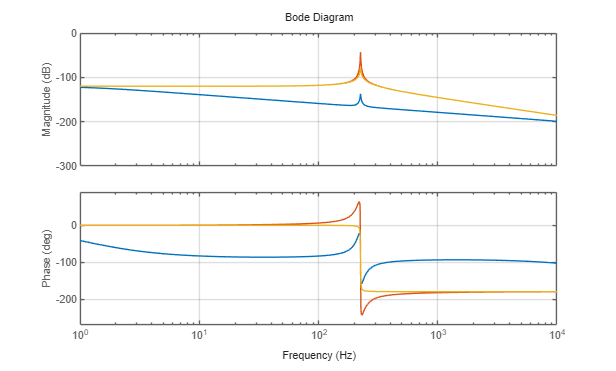

w_notch = 225 * 2* pi;
w_1 = w_notch;
w_2 = w_notch;
Q_1 = 5;
Q_2 = Q_1/1000;
Q_22 = Q_1 * 50;
N_filter = ((s/w_1)^2 + (s/(w_1 * Q_1)) + 1) /...
       ((s/w_2)^2 + (s/(w_2 * Q_2)) + 1);

N_filter_2 = ((s/w_1)^2 + (s/(w_1 * Q_1)) + 1) /...
       ((s/w_2)^2 + (s/(w_2 * Q_22)) + 1);

bode(N_filter * mass_spring_plant,...
    N_filter_2 * mass_spring_plant, mass_spring_plant,opts);